clear; clc; close all;

%% Parámetros físicos
m = 3;            % masa [kg]
l = 0.47;         % largo total de la barra [m]
I = (1/12)*m*l^2; % inercia de barra uniforme respecto al centro

% Dinámica: theta¨ = a * u, con u = (f2 - f1)
a = (l)/(2*I);      % OJO: es (l/2)/I, no (l/2*I)
%% Planta continua: G(s) = a/s
Gc = tf(a,[0 1 0])


Gc =
 
  4.255
  -----
    s
 
Continuous-time transfer function.


%% Controlador PID continuo
wc = 0.5;               % ajusta más chico si se ve muy agresivo
Cc = pidtune(Gc,"PID",wc);

Kp_c = Cc.Kp;
Ki_c = Cc.Ki;
Kd_c = Cc.Kd;

fprintf("Controlador PID continuo:\n");

Controlador PID continuo:


fprintf("  Kp_c = %.4f\n",Kp_c);

  Kp_c = 0.1153


fprintf("  Ki_c = %.4f\n",Ki_c);

  Ki_c = 0.0113


fprintf("  Kd_c = %.4f\n\n",Kd_c);

  Kd_c = 0.0000




%% Discretización
Ts = 0.015;
Gz = c2d(Gc,Ts,"zoh");

%% PID discreto diseñado sobre planta discreta
Cz = pidtune(Gz,"PID");

Kp_d = Cz.Kp;
Ki_d = Cz.Ki;
Kd_d = Cz.Kd;

fprintf("Controlador PID discreto:\n");

Controlador PID discreto:


fprintf("  Kp_d = %.4f\n",Kp_d);

  Kp_d = 0.2313


fprintf("  Ki_d = %.4f\n",Ki_d);

  Ki_d = 0.0453


fprintf("  Kd_d = %.4f\n\n",Kd_d);

  Kd_d = 0.0017



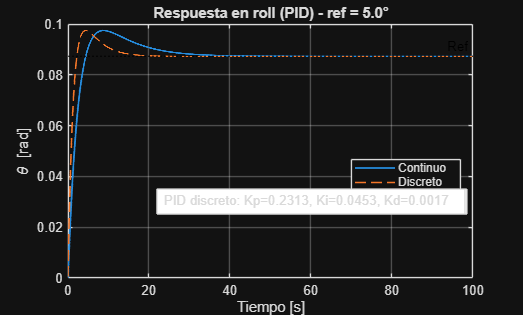


%% Lazos cerrados (de ref θ a θ)
CLc = feedback(Gc*Cc,1,-1);   % continuo
CLz = feedback(Gz*Cz,1,-1);   % discreto

%% Referencia de 5 grados
theta_ref_deg = 5;
theta_ref = theta_ref_deg*pi/180;

t_final = 100;
t = 0:Ts:t_final;

[theta_c,t_c] = step(theta_ref*CLc,t);
[theta_d,t_d] = step(theta_ref*CLz,t);

%% (Opcional) fuerzas con modelo discreto simplificado:
% Aquí, en vez de usar TF para u, puedes más adelante implementar
% la ecuación discreta del PID tú mismo en un bucle y obtener u[k].
% Por ahora, solo grafiquemos θ para verificar estabilidad.

figure;
plot(t_c,theta_c,'LineWidth',1.4); hold on;
plot(t_d,theta_d,'--','LineWidth',1.2);
yline(theta_ref,'k:','Ref','LineWidth',1);
grid on;
xlabel('Tiempo [s]');
ylabel('\theta [rad]');
title(sprintf('Respuesta en roll (PID) - ref = %.1f°',theta_ref_deg));
legend('Continuo','Discreto','Referencia','Location','Best');
%% Mostrar valores PID en el gráfico
str_c = sprintf('PID continuo: Kp=%.4f, Ki=%.4f, Kd=%.4f',Kp_c,Ki_c,Kd_c);
str_d = sprintf('PID discreto: Kp=%.4f, Ki=%.4f, Kd=%.4f',Kp_d,Ki_d,Kd_d);

% Usamos annotation para que quede fijo en la figura
annotation('textbox',...
           'String',str_c,...
           'FitBoxToText','on',...
           'BackgroundColor','w');

annotation('textbox',...
           'String',str_d,...
           'FitBoxToText','on',...
           'BackgroundColor','w');